data = readtable("vent_valve/ColdFlow201022.csv");

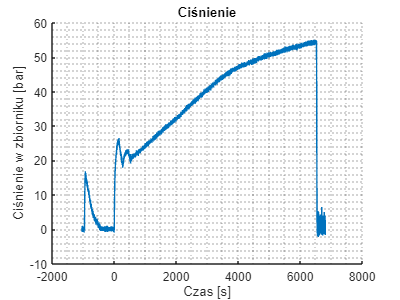


time = data.TimeSinceTankingStart_s_;
p_tank = data.PressureInTank_bar_;
mass_ox_tank = data.MassOfOxidizerInTank_kg_;
temperauture_ox = data.TemperatureOfOxidizer__C_;
mass_ox_ejected_from_bottle = data.MassOfOxidizerEjectedFromBottle_kg_;
figure
hold on
grid minor;
title('Ciśnienie');
plot(time, p_tank)
xlabel('Czas [s]');
ylabel('Ciśnienie w zbiorniku [bar]');
hold off

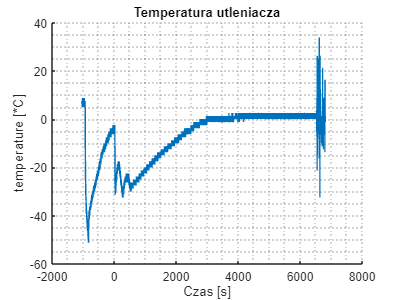



figure
hold on
grid minor;
title('Temperatura utleniacza');
plot(time,temperauture_ox);
xlabel('Czas [s]');
ylabel('temperature [*C]');
hold off

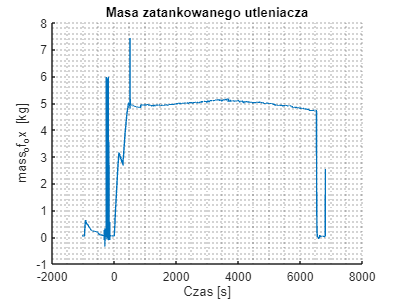



figure
hold on
grid minor;
title('Masa zatankowanego utleniacza');
plot(time,mass_ox_tank)
xlabel('Czas [s]');
ylabel('mass_of_ox [kg]');
hold off



%% tutaj biore odcinek czasu gdy poraz pierwszy zostal zamkniety eleketrozawor
t1_elektrovalve_closed=152.25; 
t2_elektrovalve_opened=280.55;
indx_time_only_vent_opened = find(time>=t1_elektrovalve_closed & time<=t2_elektrovalve_opened);
loss_mass_of_ox = mass_ox_tank(indx_time_only_vent_opened(end))-mass_ox_tank(indx_time_only_vent_opened(1));%%kg



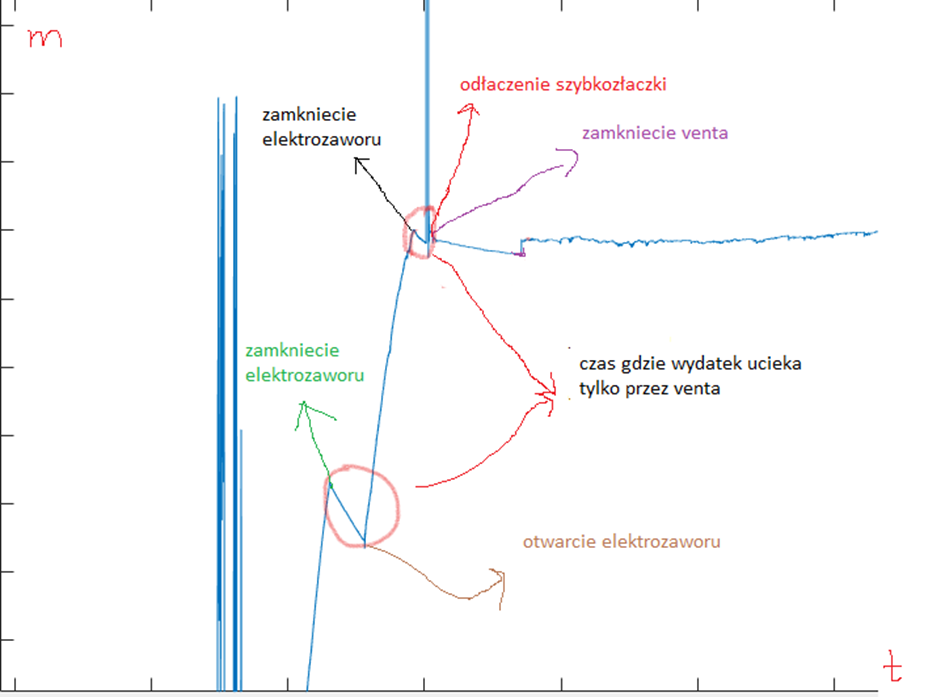

## dm/dt = C * A * [2*q*(P2-Pa)]^(1/2)

D_vent = 0.0006;%m
A = (D_vent/2)^2*pi %m^2

A = 2.8274e-07

Pa = 0 %bar; zmieniłam potem z 1 na 0, bo cisnienie w zbiorniku jest juz chyba wzgledne

Pa = 0

P_ox = p_tank(indx_time_only_vent_opened(1):indx_time_only_vent_opened(end)); %%cisnienie w zbiorniku dla badanego odcinka czasu


## funkcja gęstości utleniacza od temp

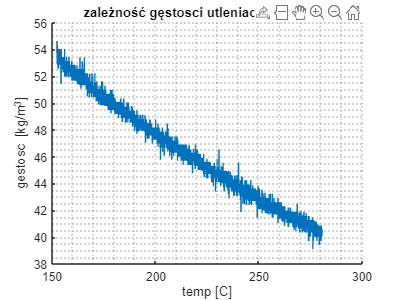

%zakładamy ze wydatek z venta to tylko faza gazowa utleniacza, dane ze strony NIST
%%temp_gestosc = readtable("gestosc od temp.xlsx");
%%temp_gestosc.Properties.VariableNames{1} = 'temp[C]';
%%emp_gestosc.Properties.VariableNames{2} = 'gestosc[kg/m^3]';
%%emp = temp_gestosc.("temp[C]");
%%gestosc = temp_gestosc.("gestosc[kg/m^3]");
% funkcja przyblizająca zaleznosc gestosci od temp
%%p = polyfit(temp,gestosc,5);
%%y1 = polyval(p,temp);

%%figure
%%plot(temp,gestosc,'r')
%%xlabel('temp [C]');
%%ylabel('gestosc [kg/m^3]');
%%hold on
%%plot(temp,y1,'b')
%%hold off
%%gestosc_ox = polyval(p,temperauture_ox);
%%gestosc_ox_2 = gestosc_ox(indx_time_only_vent_opened(1):indx_time_only_vent_opened(end));
 %%
 time2= time(indx_time_only_vent_opened(1):indx_time_only_vent_opened(end));
 R= 8.3145;%J/molK
 u = 0.04401;%kg/mol
 B = R/u;
 gestosc_ox = 100000*p_tank./((temperauture_ox+273.15)*B);
 gestosc_ox_2 = 100000*p_tank(indx_time_only_vent_opened)./((temperauture_ox(indx_time_only_vent_opened)+273.15)*B);
 figure
 grid minor;
 title('zależność gęstosci utleniacza od czasu');
 xlabel('temp [C]');
 ylabel('gestosc [kg/m^3]');
 hold on
 plot(time2,gestosc_ox_2)
 hold off

bar2Pascal = 100000;



$\int_{\textrm{t1}\_\textrm{elektrovalve}\_\textrm{closed}}^{\textrm{t2}\_\textrm{elektrovalve}\_\textrm{opened}} C\cdot A\cdot \sqrt{2\cdot \textrm{gestosc}\_\textrm{ox}\left(t\right)\cdot \left(P_{\textrm{ox}} \left(t\right)-P_a \right)}$dt = loss_mass_of_ox

##  wydatek masowy dla C=1

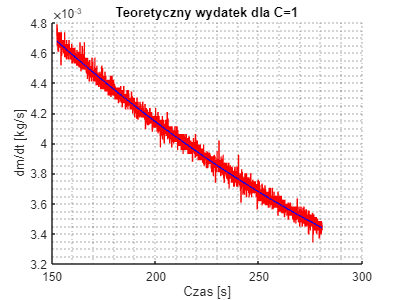


m = A.*(2.*gestosc_ox_2.*(P_ox - Pa).*bar2Pascal).^(1/2);
p2 = polyfit(time2,m,2);
y2 = polyval(p2,time2);
figure
hold on
grid minor;
title('Teoretyczny wydatek dla C=1');
plot(time2,m,'r')
plot(time2,y2,'b')
xlabel('Czas [s]');
ylabel('dm/dt [kg/s]');
hold off

% całka z wydatku po czasie
x = time2;
fun = @(x) p2(1).*x.^2 + p2(2).*x + p2(3);
m2 = integral(fun,time2(1),time2(end));


## wsp start C

% wsp C mozna wyciagnac przed całke, stąd  ponizsza rownosc

C = loss_mass_of_ox/m2

C = -0.8307

**Sprawdzenie obliczen -inny sposob, liczenie dm/dt**

% mass_spr = mass_ox_tank(indx_time_only_vent_opened);
% masa_do_atm = mass_spr(1)-mass_spr;
% p3 = polyfit(time2,masa_do_atm,2)
% y3 = polyval(p3,time2);
% figure
% hold on
% plot(time2,masa_do_atm,'r')
% plot(time2,y3,'b')
% hold off
% fun2 = @(x) 2*p3(1).*x + p3(2);
% wydatek = fun2(time2);
% figure
% hold on
% plot(time2,wydatek)
% hold off
% C_D = wydatek./y2;
% figure
% hold on
% plot(time2,C_D)
% hold off
% wsp C nie wyszedl stały, co mozna było przewidziec, jest on jakas
% funkcja, ale jego srednia wyszła zblizona do poprzedniego wyniku, co
% swiadczy o poprawnosci wyników







## Obliczenie masy podtlenku zatankowanego z butli podczas całego procesu tankowania

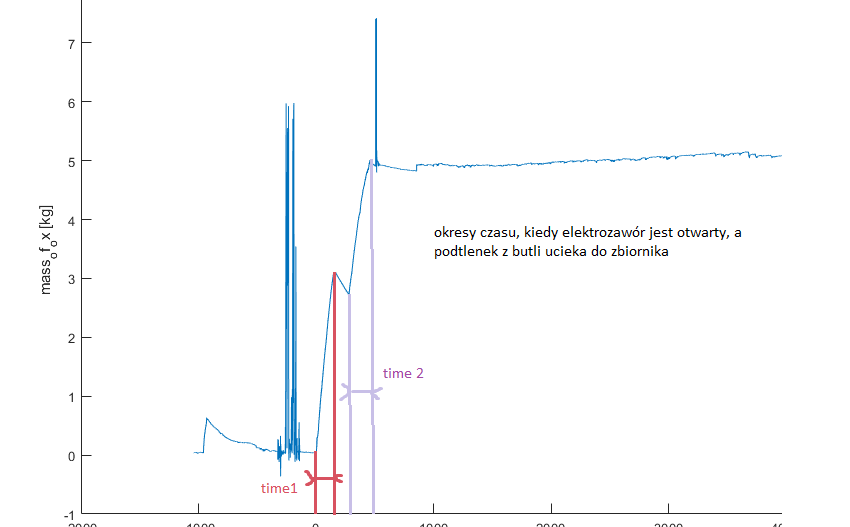

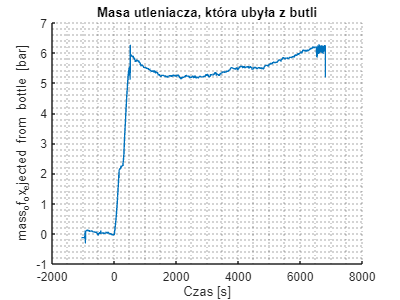

%% zakładam ze to co wyplywa z butli, wpływa do zbiornika, 
% nie licząc okresu czasu kiedy eleketrozawor jest zamkniety
% olewam tez krótki odcinek czasu miedzy zamknieciem elektrozaworu a
% odlączeniem szybkozłączki, kiedy wydatek ucieka tylko przez venta
% mozemy tez po prostu wziac przyrsot mass ejected from bottle w calym okresie
% tankowania, ale chyba mniej to wiarygodne
figure
hold on
grid minor;
title('Masa utleniacza, która ubyła z butli');
plot(time, mass_ox_ejected_from_bottle)
xlabel('Czas [s]');
ylabel('mass_of_ox_ejected from bottle [bar]');
hold off

t0_start_of_tanking = 0;
t3_end_of_tanking = 530;
indx_time_1 = find(time>=t0_start_of_tanking & time<=t1_elektrovalve_closed);
indx_time_2 = find(time>=t2_elektrovalve_opened & time<=t3_end_of_tanking);
increase_mass_of_ox_ejected_from_bottle = mass_ox_ejected_from_bottle(indx_time_1(end))-mass_ox_ejected_from_bottle(indx_time_1(1))+mass_ox_ejected_from_bottle(indx_time_2(end))-mass_ox_ejected_from_bottle(indx_time_2(1))%%kg

increase_mass_of_ox_ejected_from_bottle = 5.6637

%increase_mass_of_ox_ejected_from_bottle_2 = mass_ox_ejected_from_bottle(indx_time_2(end))-mass_ox_ejected_from_bottle(indx_time_1(1))

increase_mass_of_ox_ejected_from_bottle_2 = 5.9210

## Wydatek masowy upływający z venta w całym okresie tankowania dla wyliczonego współczynnika strat C

$\int_{\textrm{t0}\_\textrm{start}\_\textrm{of}\_\textrm{tanking}}^{\textrm{t3}\_\textrm{end}\_\textrm{of}\_\textrm{tanking}} C\cdot A\cdot \sqrt{2\cdot \textrm{gestosc}\_\textrm{ox}\left(t\right)\cdot \left(P\left(t\right)-P_a \right)}$dt = loss_mass_of_ox_whole_time_of_tanking

**Wychodzimy z załozenia ze chcmey uzyskac ostateczna mase  zatankowanego podtlenku = 5.5kg**

% ostateczna masa uzyskana przy srednicy 0.6mm =4.93kg
% masa jaką chcemy uzyskac podczas tankokwania podtlenku w zbiorniku = 5.2kg
mass_we_want = 5.2; %kg


## **Z tego wynika poniższe równanie**

# A $*\int_{\textrm{t0}\_\textrm{start}\_\textrm{of}\_\textrm{tanking}}^{\textrm{t3}\_\textrm{end}\_\textrm{of}\_\textrm{tanking}} C\cdot \sqrt{2\cdot \textrm{gestosc}\_\textrm{ox}\left(t\right)\cdot \left(P\left(t\right)-P_a \right)}$dt = increase_mass_of_ox_ejected_from_bottle - mass_we_want

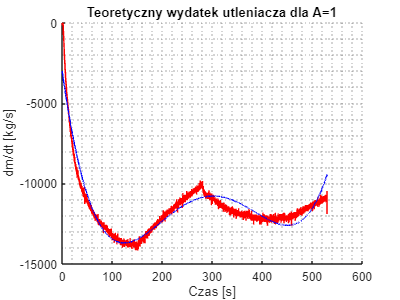

% masa która nam uciekła, czyli całka z wydatku z venta
calka = C.*(2.*gestosc_ox(indx_time_1(1):indx_time_2(end)).*(p_tank(indx_time_1(1):indx_time_2(end)) - Pa).*bar2Pascal).^(1/2);
time_tanking = time(indx_time_1(1):indx_time_2(end));
p3 = polyfit(time_tanking,calka,4);
y3 = polyval(p3,time_tanking);
figure
hold on
grid minor;
title('Teoretyczny wydatek utleniacza dla A=1');
plot(time_tanking,calka,'r')
plot(time_tanking,y3,'b')
xlabel('Czas [s]');
ylabel('dm/dt [kg/s]');
hold off

% całka z wydatku po czasie
x = time_tanking;
fun = @(x) p3(1).*x.^4 + p3(2).*x.^3 + p3(3)*x.^2+p3(4)*x+p3(5);
mass_vent_calka = integral(fun,time_tanking(1),time_tanking(end))

mass_vent_calka = -6.1250e+06

## **Szukana średnica**

A_x = (increase_mass_of_ox_ejected_from_bottle-mass_we_want)/abs(mass_vent_calka) %pole powierzchni

A_x = 7.5706e-08

D_x = 2*(abs(A_x)/pi)^(0.5)*1000%

D_x = 0.3105

% wynik moze byc niezgodny z zreczywistoscia, moze to wynikac z tego, że dane
% mass_of_ox_ejected_from_bottle opierają sie na pomiarze masy butli, co nie
% musi byc jednoznaczna z masa podtlenku która rzeczywiscie wpływa do
% zbiornika, np w okresie czasu gdy eleketrozawor jest
% zamkniety mass_of_ox_ejected_from_bottle nie jest zerowe (jakas masa nadal
% prawdopodobnie upływa do przewodu i szybkozlaczki 


## albo inaczej 

% calka z wydatku z venta dla srednicy 0.6 -to co ucieklo 
% masa jaka uzyskalismy podtlenku m = 4.93
% masa jaka chcemy uzsykac m = 5.2 kg
% masa podtlenku ktory ma nie uciec przy mniejszej srednicy x = 5.2-4.93
% calka z wydatku z venta dla srednicy 0.6  x = A *całka z wydatku dla
% szukanej srenicy


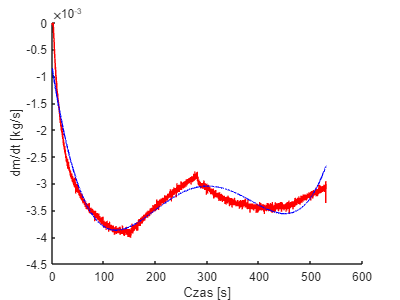

%% rzeczywista masa podltelnku która uciekła dla średnicy 0.6mm
mass_expenditure_vent = A.*C.*(2.*gestosc_ox(indx_time_1(1):indx_time_2(end)).*(p_tank(indx_time_1(1):indx_time_2(end)) - Pa).*bar2Pascal).^(1/2);
time_tanking = time(indx_time_1(1):indx_time_2(end));
p3 = polyfit(time_tanking,mass_expenditure_vent,4);
y3 = polyval(p3,time_tanking);
figure
hold on
plot(time_tanking,mass_expenditure_vent,'r')
plot(time_tanking,y3,'b')
xlabel('Czas [s]');
ylabel('dm/dt [kg/s]');
hold off

% całka z wydatku po czasie
x = time_tanking;
fun = @(x) p3(1).*x.^4 + p3(2).*x.^3 + p3(3)*x.^2+p3(4)*x+p3(5);
mass_vent = integral(fun,time_tanking(1),time_tanking(end))%tyle uciekło w teorii

mass_vent = -1.7318

 skoro końcowa masa podtlenku w zbiorniku to 4.93 kg, a chcemy uzyskać 5.5 kg, a masa która uciekła to 1.6569 kg (wynik wyzej), to wydatek jaki powinien uciec to 1.6569-(5.5-4.93)

final_mass_ox_in_tank = 4.93;
mass_ejected_from_vent_we_want = abs(mass_vent)-(mass_we_want-final_mass_ox_in_tank)

mass_ejected_from_vent_we_want = 1.4618

A_y = abs(mass_ejected_from_vent_we_want)/abs(mass_vent_calka)

A_y = 2.3866e-07

D_y = 2*(A_y/pi)^(0.5)*1000%mm

D_y = 0.5512

## bardzo rozbieżny wynik, uznano, że pierwszy sposob jest bardziej wiarygodny